Lab1_a

[y,fs] = audioread('vergleichsaudio.mp3');
t = (0:length(y)-1)/fs;

moin

sound(y,fs);

plotten

[numRows,numCols] = size(y);
 
%2Sprachkanäle, bestimme den Mittwelwert
y_avg = mean(y,numCols);
 
% Sprachsignal als Oszillogramm plotten
plot(t(1:50:end),y_avg(1:50:end));  
xlabel ('Zeit t in  [s]  \rightarrow')
ylabel ('Amplitude y(t)  \rightarrow')
title ("Oszillogramm")

Lab1_b

Konstanten

y0 = 1;   % Amplitude in Volt (V)
f0 = 440; % Grundfreqeunz Kammerton in Hertz (Hz)
fs= 20 * f0;    %Shannon-Theory (Minimu 2* f0)
nCycl = 440;    % Anzahl der kompletten Zyklen der Sinus-Welle
 
 
% Abtastzeiten
t=0:1/fs:(nCycl*1/f0)-1/fs; %time base

abtastwerte berechnen

y = y0*sin(2*pi*f0*t);       % Signalabtastwerte berechnen

plotten

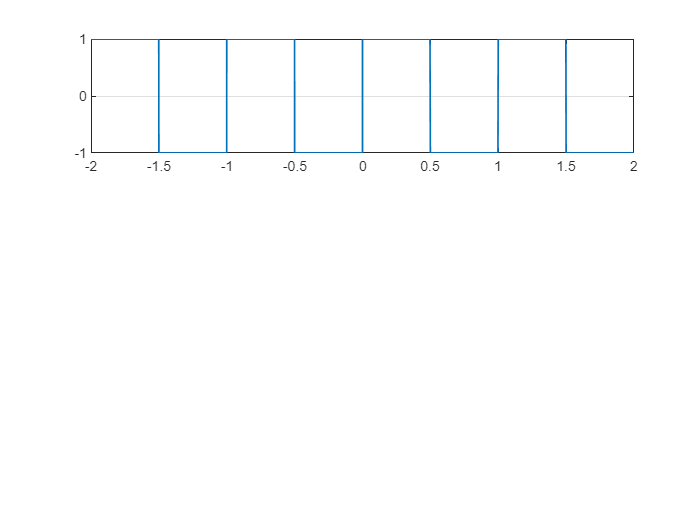

%Plotten des Oszillogramms
subplot(3,1,1), plot(t(1:50),y(1:50),'LineWidth',2), grid
title ('Ton: f=440Hz')
xlabel('Time {\itt} in seconds \rightarrow')
ylabel('{\itx}({\itt}) / {\itx}_0 \rightarrow')